# Lab Session One

## PSS signals

run("pss0.m")
run("pss1.m")
run("pss2.m")
run("pss.m")

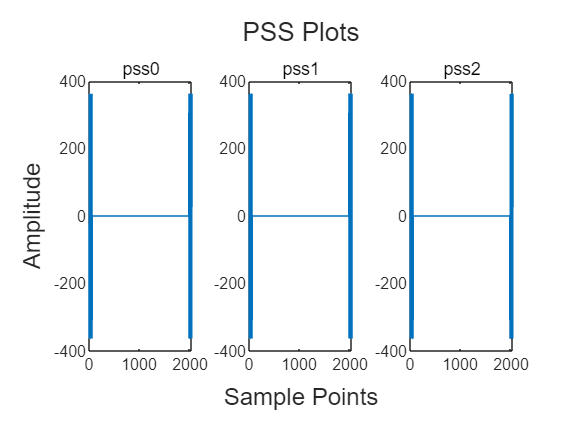

% First Figure (pss_0, pss_1, pss_2)
figure
t1 = tiledlayout(1, 3, 'TileSpacing', 'compact');
title(t1, 'PSS Plots')
xlabel(t1, 'Sample Points')
ylabel(t1, 'Amplitude')

% Plot pss_0
nexttile
plot(pss_0)
title("pss0")

% Plot pss_1
nexttile
plot(pss_1)
title("pss1")

% Plot pss_2
nexttile
plot(pss_2)
title("pss2")

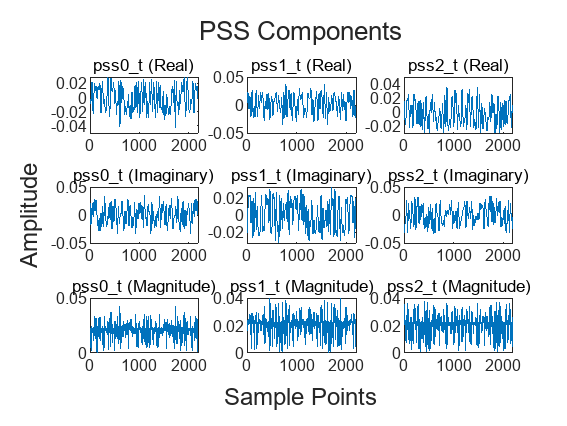


% Second Figure (Real, Imaginary, Magnitude Parts)
figure
t2 = tiledlayout(3, 3, 'TileSpacing', 'compact');
title(t2, 'PSS Components')
xlabel(t2, 'Sample Points')
ylabel(t2, 'Amplitude')

% Real Part
nexttile
plot(real(pss0_t))
title('pss0\_t (Real)')

nexttile
plot(real(pss1_t))
title('pss1\_t (Real)')

nexttile
plot(real(pss2_t))
title('pss2\_t (Real)')

% Imaginary Part
nexttile
plot(imag(pss0_t))
title('pss0\_t (Imaginary)')

nexttile
plot(imag(pss1_t))
title('pss1\_t (Imaginary)')

nexttile
plot(imag(pss2_t))
title('pss2\_t (Imaginary)')

% Magnitude
nexttile
plot(abs(pss0_t))
title('pss0\_t (Magnitude)')

nexttile
plot(abs(pss1_t))
title('pss1\_t (Magnitude)')

nexttile
plot(abs(pss2_t))
title('pss2\_t (Magnitude)')


% A1.1: No matter what component--the real part, the imaginary part 
% or the magnitude, the first parts of the signal are the same as the last
% parts of the signals


## power spectrum

fs = 61.44e6;

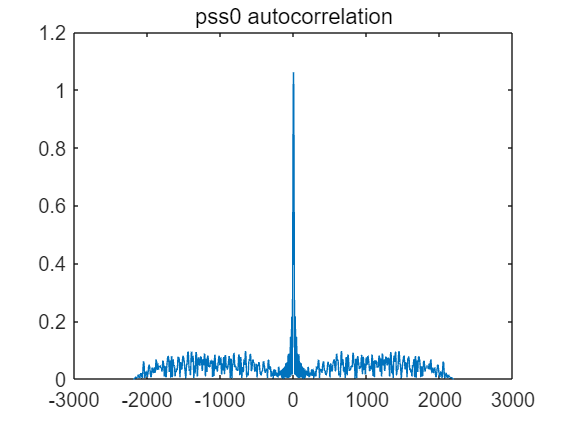

N = length(pss0_t);
x = -N+1:N-1;
figure
pss0_auc = xcorr(pss0_t,pss0_t);
plot(x,abs(pss0_auc))
title("pss0 autocorrelation")

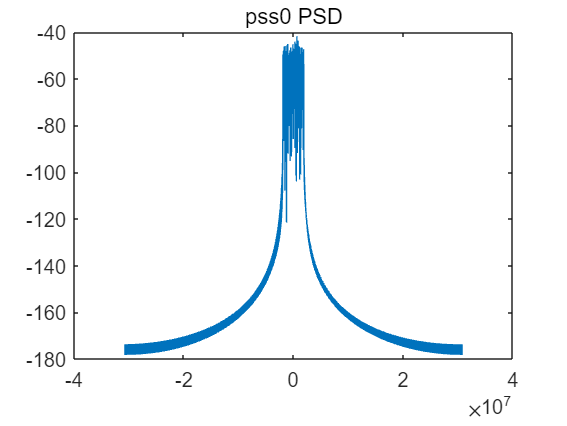

pss0_psd = fft(pss0_auc);
pss0_psd = fftshift(pss0_psd)/length(pss0_psd);
f = linspace(-fs/2,fs/2,length(pss0_psd));
plot(f,10*log(abs(pss0_psd)))
title("pss0 PSD")

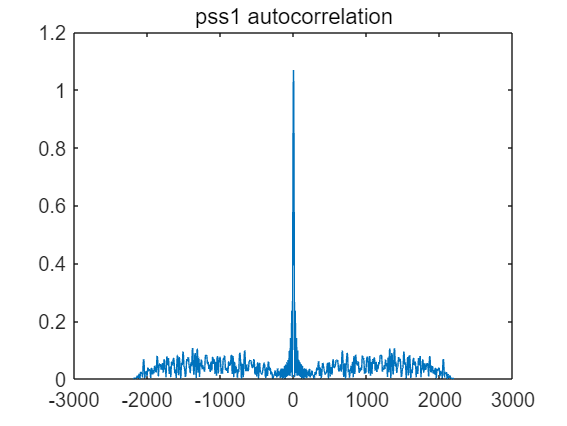

figure
pss1_auc = xcorr(pss1_t,pss1_t);
plot(x,abs(pss1_auc))
title("pss1 autocorrelation")

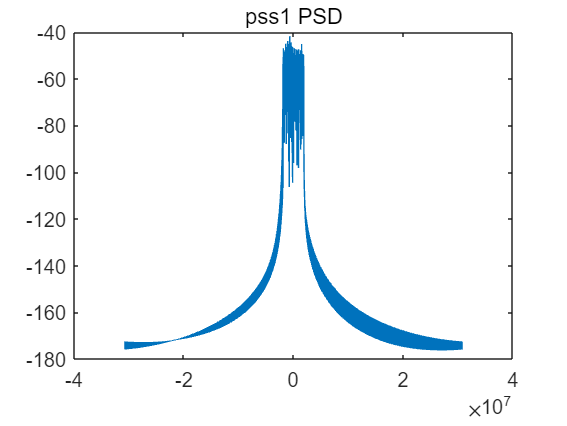

pss1_psd = fft(pss1_auc);
pss1_psd = fftshift(abs(pss1_psd))/length(pss1_psd);
f = linspace(-fs/2,fs/2,length(pss1_psd));
plot(f,10*log(abs(pss1_psd)))
title("pss1 PSD")

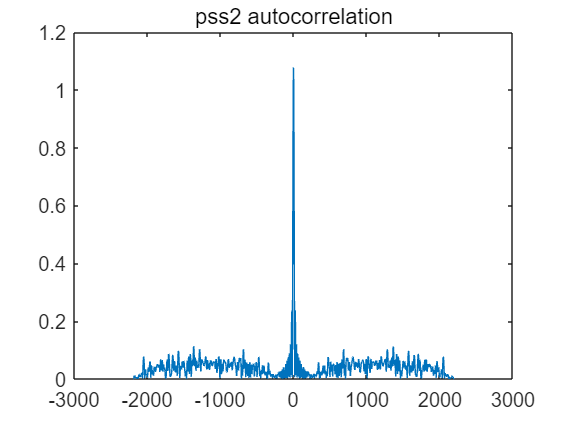

figure
pss2_auc = xcorr(pss2_t,pss2_t);
plot(x,abs(pss2_auc))
title("pss2 autocorrelation")

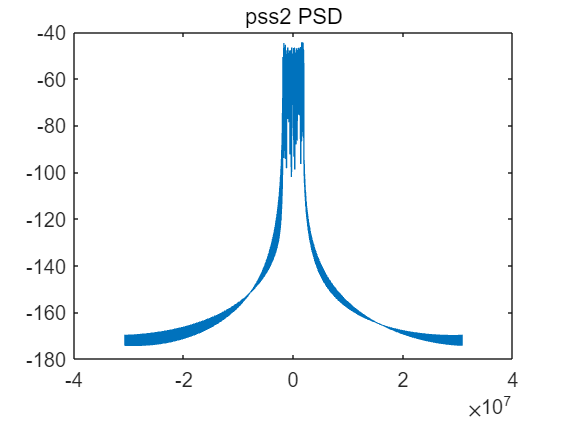

pss2_psd = fft(pss2_auc);
pss2_psd = fftshift(abs(pss2_psd))/length(pss2_psd);
f = linspace(-fs/2,fs/2,length(pss2_psd));
plot(f,10*log(abs(pss2_psd)))
title("pss2 PSD")

mean(pss0_t)

ans = -0.0015 + 0.0007i

mean(pss1_t)

ans = 0.0020 + 0.0004i

mean(pss2_t)

ans = -0.0016 - 0.0005i

% their average is close to 0

BW_0 = tdb_bandwidth(pss0_psd,fs,20)

BW_0 = 2.7895e+06

BW_1 = tdb_bandwidth(pss1_psd,fs,20)

BW_1 = 2.7335e+06

BW_2 = tdb_bandwidth(pss2_psd,fs,20)

BW_2 = 2.9718e+06

% A1.2: Here it uses 20dB from peak to measure the bandwith. Their
% bandwidths are close to 3MHz. Compare to to sampling rate(61.44MHz), 
% it's quite a narrowband signal.

## crosscorrelation

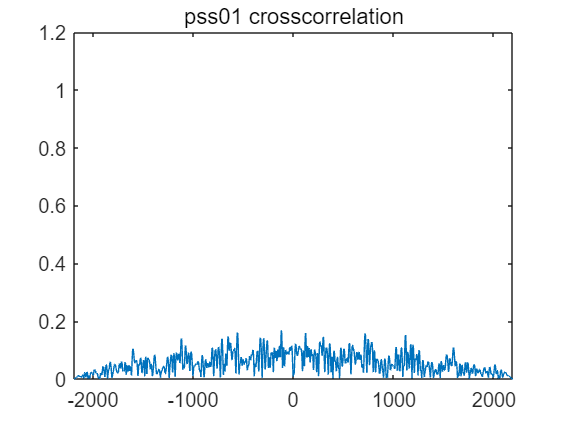

figure
pss01_ccr = xcorr(pss0_t,pss1_t);
pss02_ccr = xcorr(pss0_t,pss2_t);
pss12_ccr = xcorr(pss1_t,pss2_t);
plot(x,abs(pss01_ccr))
title("pss01 crosscorrelation")
axis([-N N 0 1.2])

interf01 = abs(pss01_ccr((length(pss01_ccr)+1)/2))

interf01 = 0.0148

interf01_dB = 10*log(interf01)

interf01_dB = -42.1322

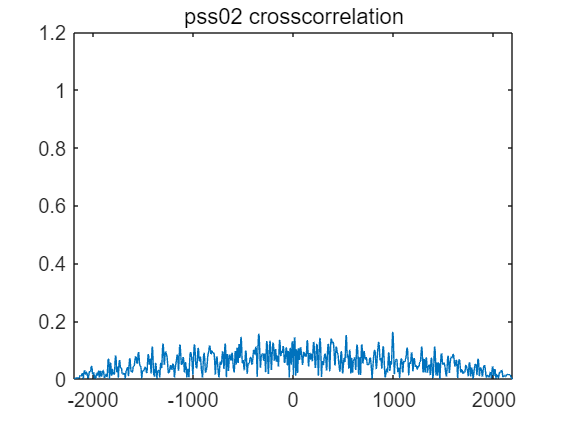

plot(x,abs(pss02_ccr))
title("pss02 crosscorrelation")
axis([-N N 0 1.2])

interf02 = abs(pss02_ccr((length(pss02_ccr)+1)/2))

interf02 = 0.0128

interf02_dB = 10*log(interf02)

interf02_dB = -43.6156

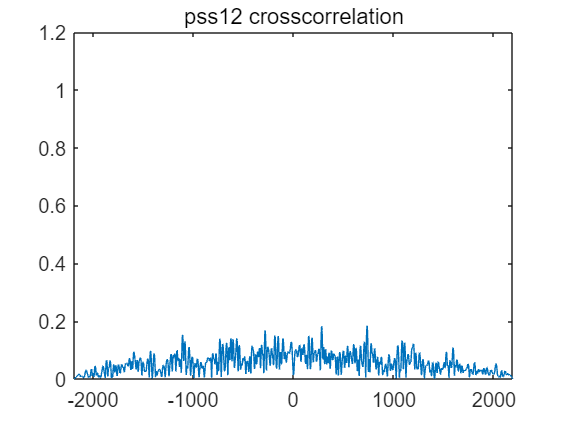

plot(x,abs(pss12_ccr))
title("pss12 crosscorrelation")
axis([-N N 0 1.2])

interf12 = abs(pss12_ccr((length(pss12_ccr)+1)/2))

interf12 = 0.0134

interf12_dB = 10*log(interf12)

interf12_dB = -43.1579

% A1.3: In these three crosscorelation results we can see, they have very 
% little amount related part. For the R(0) in autocorrelation shows the 
% energy of the signal, here it use the R(0) in corsscorrelation to imply
% the energy to interference, which neary goes to -43dB in average.

## Channel Model

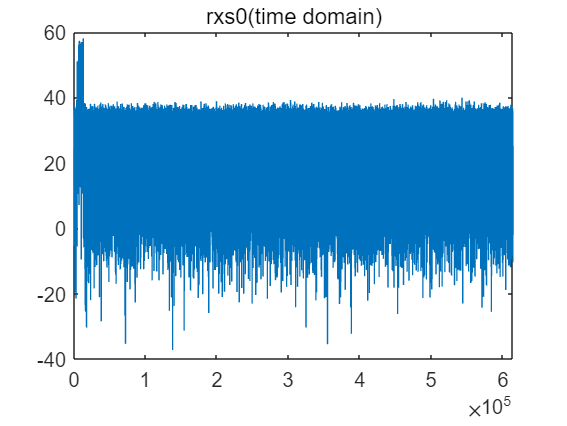

load("rxsignal_justnoise.mat")
plot(10*log(abs(rxs0)));
title("rxs0(time domain)")

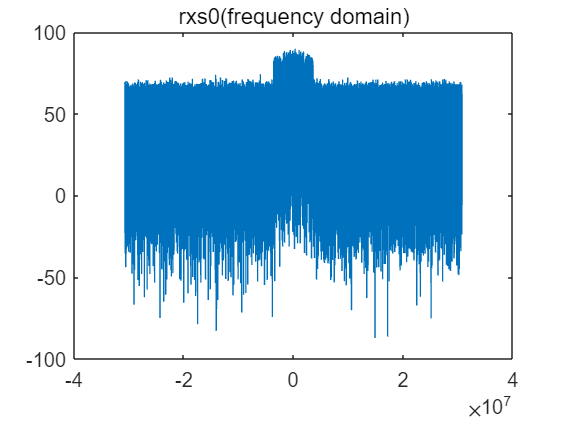

Bandwidth:
   2.2942e+06


fre_plot(rxs0,fs,"rxs0(frequency domain)",20);

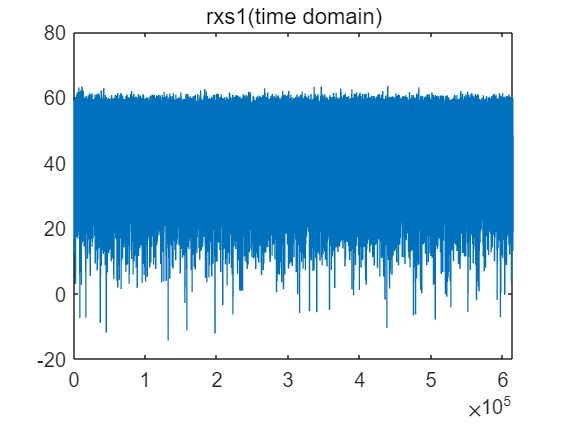

plot(10*log(abs(rxs1)));
title("rxs1(time domain)")

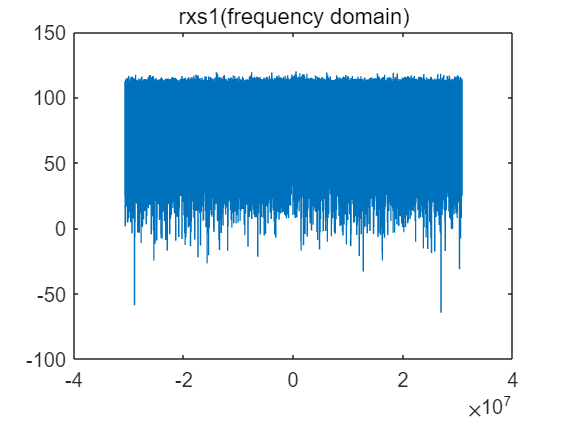

Bandwidth:
     0


fre_plot(rxs1,fs,"rxs1(frequency domain)",0);

disp("In this case, the BW is not making much sense")

In this case, the BW is not making much sense


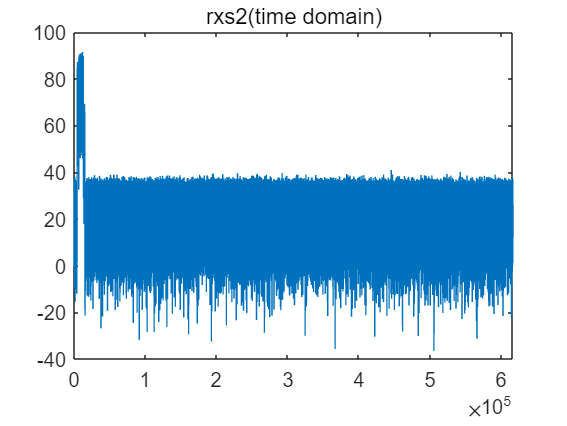

load("rxsignal_withchannel.mat")
plot(10*log(abs(rxs2)));
title("rxs2(time domain)")

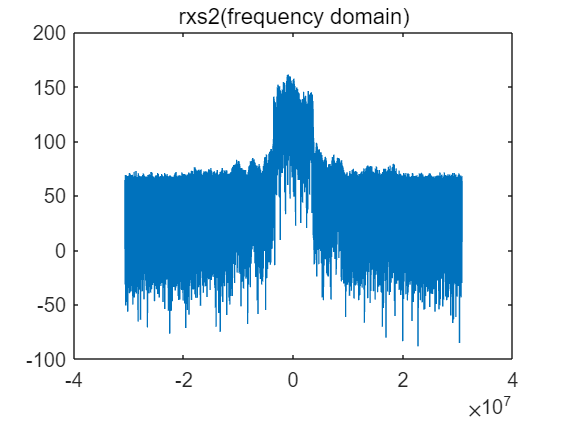

Bandwidth:
   4.6263e+06


fre_plot(rxs2,fs,"rxs2(frequency domain)",40);

%plot(atan(imag(rxs2)./real(rxs2)))

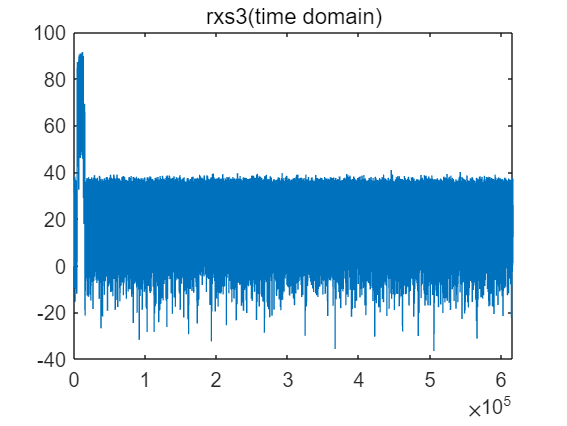

load("rxsignal_withchannelandfreqoff.mat")
plot(10*log(abs(rxs3)));
title("rxs3(time domain)")

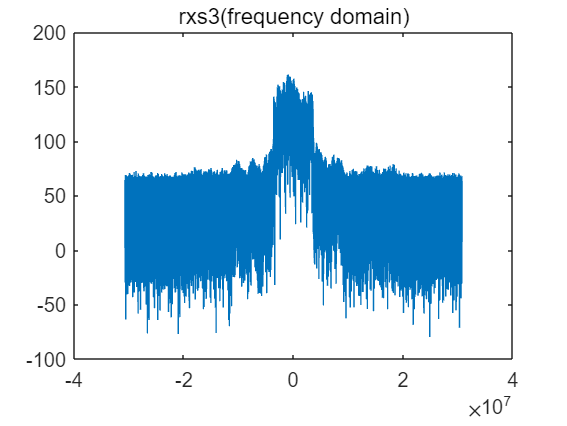

Bandwidth:
   4.6263e+06


fre_plot(rxs3,fs,"rxs3(frequency domain)",40);

%run("rx151024_real.m") %really big
% plot(10*log(abs(rxs3)));
% fre_plot(rxs3,fs,"rxs3");

%A2.1: Done
%A2.2: In the first two signals there are additive noise, it can be seen
%that the additive noise can polute both the time domain and the
%frequency domain. The latter two signals go through the channel. There're
%some delays and the BW of the recieve signal has been expanded.
%A2.3: The signal components that are located outside the band of interest
%are the noise.
%A2.4: The multipath propagation might contribute the most to the "changing
%shape". Besides, fading and doppler effect may also contribute.

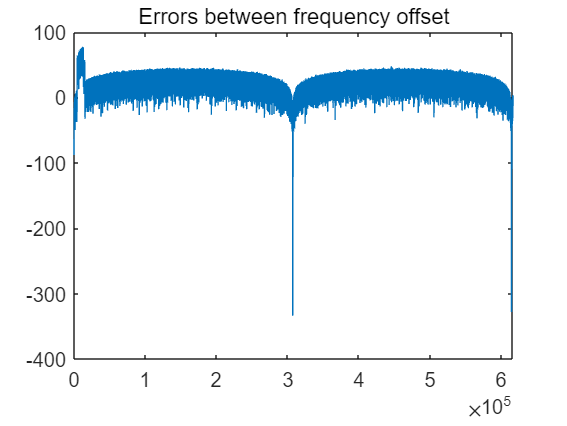

plot(10*log(abs(rxs3-rxs2)))
title("Errors between frequency offset")

## Reciever:

## ML

%A3.1 The statistic is a coherent reciever. The ML we first implement is a non-coherent reciever.
%A3.2 The first two channel they're all additive noise. If the addictive
%noise is too high, the useful signal might be buried. The later two
%channel not only induce the frequency shaping but also some delay.
%A3.3 & A3.4 DONE.




rx_sig = rxs0;
[Y1, pos] = PSS_detc(rx_sig, pss0_t, pss1_t, pss2_t);

pss2 detected
With value:


MAX_value = 1.8944e+07

In position:


ans = 4417

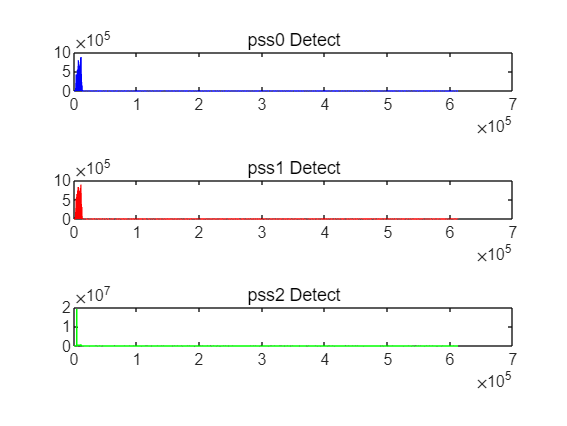

x = 1:length(Y1);
plot_together(x,abs(Y1))

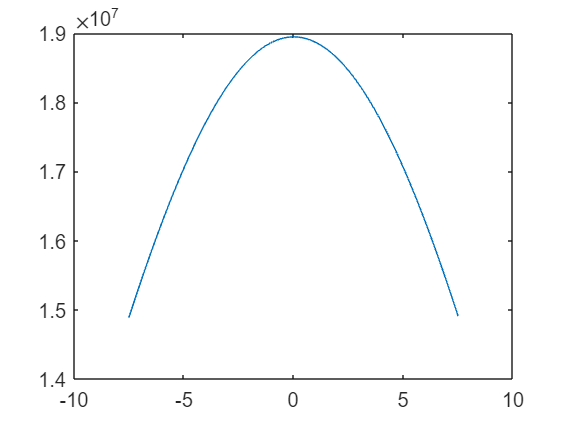

best_offset_freq = 0

max_outcome = 1.8944e+07

freq_scan = 1.0e+07 *

    1.4887    1.4984    1.5081    1.5177    1.5272    1.5366    1.5459    1.5552    1.5643    1.5734    1.5823    1.5912    1.5999    1.6086    1.6172    1.6256    1.6340    1.6422    1.6503    1.6584    1.6663    1.6741    1.6818    1.6893    1.6968    1.7041    1.7114    1.7184    1.7254    1.7323    1.7390    1.7456    1.7520    1.7584    1.7646    1.7706    1.7766    1.7824    1.7881    1.7936    1.7990    1.8042    1.8093    1.8143    1.8191    1.8238    1.8284    1.8328    1.8370    1.8411



[best_offset_freq, max_outcome, freq_scan] = freq_offset_detect(pss2_t,rx_sig,7.5,2,fs)

rx_sig = rxs1;
[Y, pos] = PSS_detc(rx_sig, pss0_t, pss1_t, pss2_t);
x = 1:length(Y);
plot_together(x,abs(Y))

rx_sig = rxs2;
[Y, pos] = PSS_detc(rx_sig, pss0_t, pss1_t, pss2_t);
x = 1:length(Y);
plot_together(x,abs(Y))

rx_sig = rxs3;
[Y, pos] = PSS_detc(rx_sig, pss0_t, pss1_t, pss2_t);
x = 1:length(Y);
plot_together(x,abs(Y))

## MF

rx_sig = rxs0;
[Y2, pos] = PSS_MFdetc(rx_sig, pss0_t, pss1_t, pss2_t);
x = 1:length(Y2);
plot_together(x,abs(Y2)')

rx_sig = rxs1;
[Y, pos] = PSS_MFdetc(rx_sig, pss0_t, pss1_t, pss2_t);
x = 1:length(Y);
plot_together(x,abs(Y)')

rx_sig = rxs2;
[Y, pos] = PSS_MFdetc(rx_sig, pss0_t, pss1_t, pss2_t);
x = 1:length(Y);
plot_together(x,abs(Y)')

rx_sig = rxs3;
[Y, pos] = PSS_MFdetc(rx_sig, pss0_t, pss1_t, pss2_t);
x = 1:length(Y);
plot_together(x,abs(Y)')
[best_offset_freq, max_outcome, freq_scan] = freq_offset_detect(pss2_t,rx_sig,7.5,2,fs)

% [Y_max,pos] = max(abs(Y));
% [MAX_value,MAX_order] = max(Y_max);
% if MAX_order == 1
%     fprintf("pss0 detected")
% elseif MAX_order == 2
%     fprintf("pss1 detected")
% elseif MAX_order == 3
%     fprintf("pss2 detected")
% end

% load("output_imag_data_part1.mat")
% load("output_real_data_part1.mat")
% a = 1+1j;
% rx151024_real = cast(rx151024_real,'like',a);
% rx151024_imag = cast(rx151024_imag,'like',a)*1j;
% rx151024 = rx151024_real + rx151024_imag;

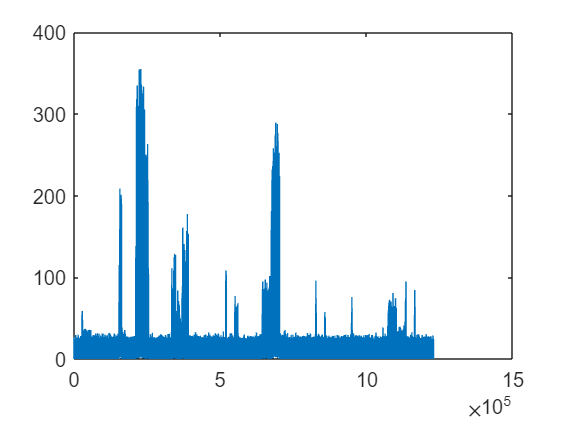

load("rx151024mat.mat")
figure
plot(abs(rx151024))

rx_sig = rx151024;
[Y, pos] = PSS_detc(rx_sig, pss0_t, pss1_t, pss2_t);
x = 1:length(Y);
Y_ = abs(Y);
%%plot(x,Y_(:,1)',x,Y_(:,2)',x,Y_(:,3)')
plot_together(x,Y_)

rx_sig = rx151024;
[Y, pos] = PSS_MFdetc(rx_sig, pss0_t, pss1_t, pss2_t);

pss0 detected
With value:


MAX_value = 4.4383e+06

In position:


ans = 382082

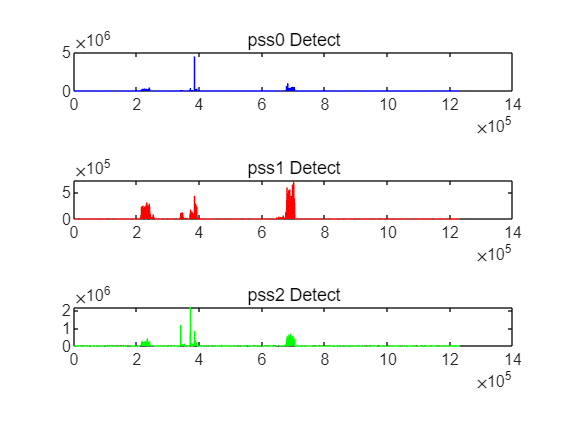

x = 1:length(Y);
Y_ = abs(Y);
%%plot(x,Y_(:,1)',x,Y_(:,2)',x,Y_(:,3)')
plot_together(x,Y_')

x = 1:length(Y);
Y_ = abs(Y);
%%plot(x,Y_(:,1)',x,Y_(:,2)',x,Y_(:,3)')
plot_together(x,Y_')


function BW = tdb_bandwidth(spc,fs,dB_value)
%change dB_value to define bandwidth
spc = 10*log(abs(spc));
peak = max(spc);
a = find(spc> peak-dB_value);
BW = length(a)/length(spc)*fs;
end

function spc = fre_plot(s, fs, Title, dB_value)
s_acr = xcorr(s,s);
fft_s = fft(s_acr)/length(s_acr);
fft_s = fftshift(abs(fft_s));
f = linspace(-fs/2,fs/2,length(s_acr));
spc = abs(fft_s);
plot(f,10*log(spc))
title(Title);
BW = tdb_bandwidth(spc,fs, dB_value);
disp("Bandwidth:")
disp(BW)
end

function [Y, pos, Y_max] = MLD(rx_sig, pss)
[l_r,~] = size(rx_sig);
[n,l_o] = size(pss);
l = l_r - l_o;
Y = zeros(l,n);
for i = 1:l
    Y(i,:) = sum((rx_sig(i:i+l_o - 1,:).*pss')).^2;
end
[Y_max,pos] = max(abs(Y));
end

function [Y, pos, Y_max] = MFD(rx_sig, pss)
MF_pss = flip(pss,2);
[m,~] = size(pss);
Y = [];
for i = 1:m
    Y = [Y;conv(MF_pss(i,:),rx_sig(:,i)').^2];
end
[Y_max,pos] = max(abs(Y'));
end

function [Y_joint,pos] = PSS_detc(rx_sig, pss0,pss1,pss2)
pss = [pss0;pss1;pss2];
Rx_sig = [rx_sig,rx_sig,rx_sig];
[Y_joint, pos, Y_max] = MLD(Rx_sig, pss);
[MAX_value,MAX_order] = max(Y_max);
if MAX_order == 1
    disp("pss0 detected")
elseif MAX_order == 2
    disp("pss1 detected")
elseif MAX_order == 3
    disp("pss2 detected")
end
disp('With value:')
MAX_value
disp('In position:')
pos(MAX_order)
%print(MAX_value)
end

function [Y_joint,pos] = PSS_MFdetc(rx_sig, pss0,pss1,pss2)
pss = [pss0;pss1;pss2];
Rx_sig = [rx_sig,rx_sig,rx_sig];
[Y_joint, pos, Y_max] = MFD(Rx_sig, pss);
[MAX_value,MAX_order] = max(Y_max);
if MAX_order == 1
    disp("pss0 detected")
elseif MAX_order == 2
    disp("pss1 detected")
elseif MAX_order == 3
    disp("pss2 detected")
end
disp('With value:')
MAX_value
disp('In position:')
pos(MAX_order)-length(pss0)+1
%print(MAX_value)
end

function plot_together(x,Y)
figure
subplot(3,1,1)
plot(x,Y(:,1)',"Color","b")
title("pss0 Detect")
subplot(3,1,2)
plot(x,Y(:,2)',"Color","r")
title("pss1 Detect")
subplot(3,1,3)
plot(x,Y(:,3)',"Color","g")
title("pss2 Detect")
end

function [best_offset_freq, max_outcome, freq_scan] = freq_offset_detect(pssi,rx,fre_band,type,fs)
%if type = 1, ML; if type = 2, MF
%never use 1, far too slow!!!
Fre = -fre_band:0.1:fre_band;%testing frequency
best_offset_freq = -10;
freq_scan = zeros(1, length(Fre));%outcome storage
n = 1: length(pssi);
max_outcome = 0;
for fre = 1:length(Fre)
    offset_seq = exp(-2*pi.*n*1j*Fre(fre)*1e3/fs);
    if type == 1
        [~, ~, freq_scan(fre)] = MLD(rx, offset_seq.*pssi);
    end
    if type == 2
        [~, ~, freq_scan(fre)] = MFD(rx, offset_seq.*pssi);
    end
    if freq_scan(fre) > max_outcome
        max_outcome = freq_scan(fre);
        best_offset_freq = Fre(fre);
        %Best_fre = fre;
    end
    %disp("Testing order:")
    %fre
end
figure
plot(Fre,freq_scan)
end